# Chap 21 Prob 36 with F-sinusoid Added

Solve 21.36 with addition of a sinusiodal force F.


$$\ddot{x}+2\zeta\omega_n\dot{x}+\omega_n^2=\frac{1}{m}[10\sin({\Omega t})]$$


The parameter values for Prob 36-38 are specified below. Any consistent units are valid.

clear
m = 2; % mass
k = 72; % spring constant
c = 0.5; % damping constant
F = 10; % excitation force
Freq = 4; % excitation freq (rad/s)
x0 = 0; % initial position
v0 = 0; % initial velocity
t0 = 0; % initial time
tf = 50; % final time
ntime = 1001; % number of time points

Key parameter values

omegan = sqrt(k/m)

omegan = 6

zeta = c/(2*m*omegan)

zeta = 0.0208

omegad = omegan*sqrt(1-zeta^2)

omegad = 5.9987

## Step 8: Solve the EOM, Solve the Problem

### Numerical Solution

[T S] = ode45(@(t,s)eom(t,s,m,k,c,F,Freq),linspace(t0,tf,ntime),[x0,v0]);

### Post-Process and Interpret Results

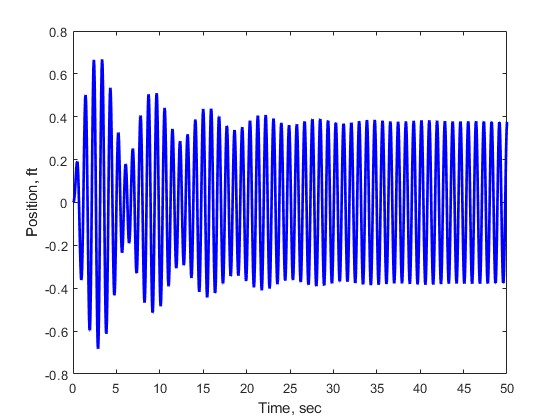

plot(T,S(:,1),'-b','linewidth',2)
xlabel('Time, sec')
ylabel('Position, ft')

%fprintf('Numerical solution for final position is %6.3f ft \n',S(end,1))
fprintf('Peak amplitude at steady state is %6.3f ft \n',max(S(end-100:end,1)))

Peak amplitude at steady state is  0.379 ft/s 


function sdot = eom(t,s,m,k,c,F,Freq)
sdot(1,1) = s(2);
sdot(2,1) = 1/m*(F*sin(Freq*t)-c*s(2)-k*s(1));
end